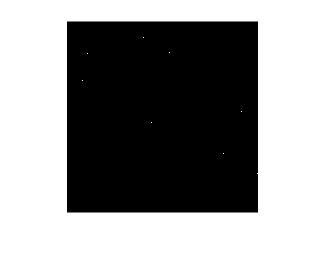

%Matriz de colores
c=[255 0 0; 0 255 0; 0 0 255; 255 255 0;
   0 255 255; 255 0 255; 128 0 0; 0 128 0;
   0 0 128; 128 0 128; 128 128 0; 0 128 128;
   128 128 128; 255 0 128; 128 0 255; 255 128 0];

%Se genera la matriz inicial para la imagen y para los nodos aleatorios
im = zeros(256);
p=randi([1,256],16,2);

%Se colocan los nodos
for i=1:16
    im(p(i,1),p(i,2))=255;
end

imshow(uint8(im))

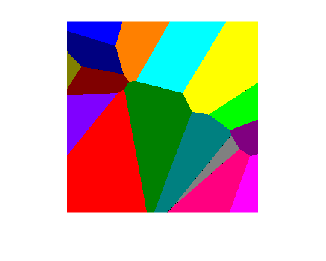


%Se genera el Mapa de Voronoi
for x=1:256
    for y=1:256
        %Se obtiene la distancia para cada punto
        for z=1:16
            d(z)=sqrt((p(z,1)-x)^2+(p(z,2)-y)^2);
        end
        %Se obtiene el nodo más cercano
        [V,ind]=min(d);
        %Si solo un nodo es el más cercano se colorea
        if size(find(d==V))==1
            im(x,y,1)=c(ind,1);
            im(x,y,2)=c(ind,2);
            im(x,y,3)=c(ind,3);
        %Si el punto es igual de cercano a 2 o más nodos se mantiene en
        %negro
        else
            im(x,y,1)=0;
            im(x,y,2)=0;
            im(x,y,3)=0;
        end
    end
end

imshow(uint8(im))